# Custom XY Example for Supported DSPC layer.

In this example, we model the same data (DSPC supported bilayer) as the Custom Layers example, but this time we will use continuous distributions of the volume fractions of each component to build up the SLD profiles (as described in Shekhar et al, *J. Appl. Phys.*, **110**, 102216 (2011). )

In this type of model, each 'layer' in the sample is described by a roughened Heaviside step function (really, just two error functions back to back). So, in our case, we will need an oxide, a (possible) intervening water layer, and then the bilayer itself.

We can define our lipid in terms of an Area per Molecule, almost in it's entirity, if we recognise that where the volume is known, the thickness of the layer is simply given by the layer volume / APM

$d_{\textrm{layer}} =\frac{V_{\textrm{layer}} }{{\textrm{APM}}_{\textrm{layer}} }$.

We can then define the Volume Fraction of this layer with a roughened Heaviside of length dlayer and a height of 1. Then, the total volume occupied will be given by the sum of the volume fractions across the interface. Of course, this does not permit any hydration, so to deal with this, we can simply scale the (full occupation) Heaviside functions by relevant coverage parameters. When this is correctly done, we can obtain the remaining water distribution as


$${\textrm{VF}}_{\textrm{wat}} =1-\sum_n {\textrm{VF}}_n$$


where VFn is the Volume Fraction of the n'th layer. 

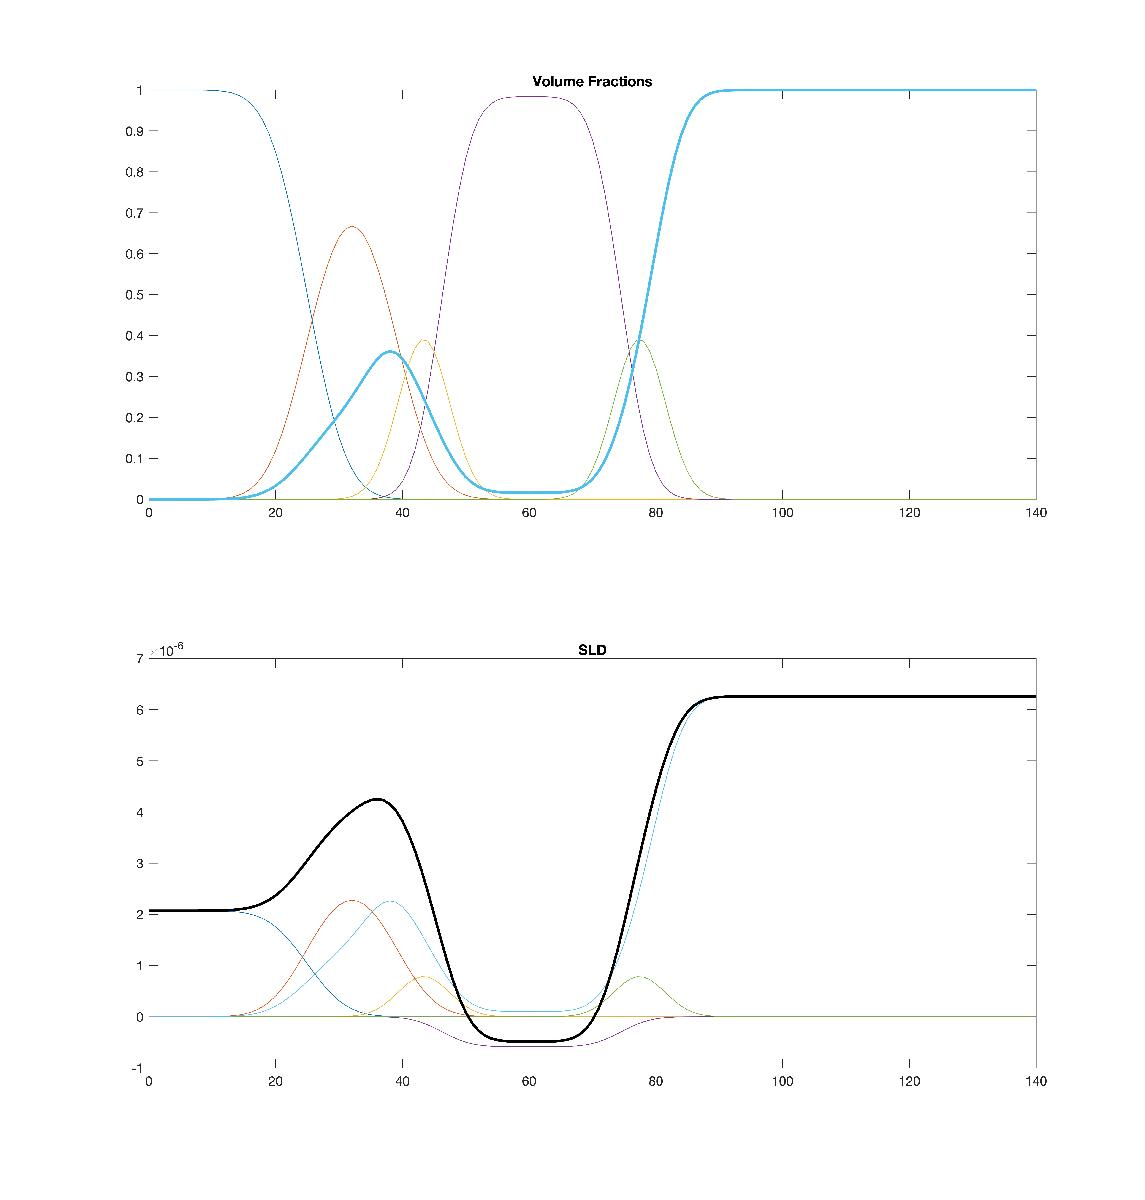

Start by making the class and setting it to a custom layers type:

problem = createProject(name='Orso lipid example - custom XY', model='custom XY');
problem.setGeometry('Substrate/liquid');
problem.setUsePriors(true);

We need to add the relevant parameters we are going to need to define the model (note that Substrate Roughness' always exists as parameter 1..

Parameters = {
    %       Name                min          val         max        fit? 
        {'Oxide Thick'          10           15          30         true};
        {'Oxide Hydration'      0.1          0.2         0.4        true};
        {'Water Thick'          0,           5          20         true};
        {'Lipid APM'            40           50          90         true};
        {'Lipid Coverage'       0.9          1.0         1.0        true};
        {'Bilayer Rough'        3            5           8          true};
        };
    
 problem.addParameterGroup(Parameters);
 problem.setParameter(1,'min',1,'max',10);

Need to add the relevant Bulk SLD's. Change the bulk in from air to silicon, and add two additional water contrasts:

% Change bulk in from air to silicon....
problem.setBulkIn(1,'name','Silicon','min',2.07e-6,'value',2.073e-6,'max',2.08e-6,'fit',false);

% Add two more values for bulk out....
problem.addBulkOut('SLD SMW',1e-6,2.073e-6,3e-6,true);
problem.addBulkOut('SLD H2O',-0.6e-6,-0.56e-6,-0.3e-6,true);

problem.setBulkOut(1,'fit',true,'min',5e-6,'value',6.1e-6);

Now add our datafiles...... 

% Read in the datafiles....
D2O_data = dlmread('c_PLP0016596.dat');
SMW_data = dlmread('c_PLP0016601.dat');
H2O_data = dlmread('c_PLP0016607.dat');

% Add the data to the project
problem.addData('Bilayer / D2O', D2O_data);
problem.addData('Bilayer / SMW', SMW_data);
problem.addData('Bilayer / H2O', H2O_data);

problem.setData(2,'dataRange',[0.013 0.37]);
problem.setData(3,'dataRange',[0.013 0.37]);
problem.setData(4,'dataRange',[0.013 0.37]);

Add the custom file to the project.... we can view the code first.....

(Note that here we are making an optional third output parameter, which we need later just for plotting, but not for the RAT fit. So, we make this output optional using a global flag, so that we can control it from outside our function....)

global outputVF;
outputVF = false;
type('customXYDSPC.m')

function [SLD, subRough, varargout] = DSPC_Custom_XY_2(params,bulk_in,bulk_out,contrast)

% This function makes a model of a supported DSPC bilayer using volume
% restricted distribution functions.


debug = false;      % controls.whether we make debug plot....

global outputVF;    % This is a flag which controls if we output our VF's.
                    % If this is set to 'false', then this function can be
                    % used as a RAT custom function (otherwise RAT will
                    % fail with 'too many outputs' error....). Set to
                    % 'true', the third (optional) output parameter is our
                    % Volume Fractions.

% Split up the parameters
subRough = params(1);
oxideThick = params(2);
oxideHydration = params(3);
waterThick = params(4);
lipidAPM = params(5);
lipidCoverage = params(6);
bilayerRough = params(7);

% We are going to need our Neutron scattering cross sections, plus the
% component volumes (the volumes are taken from Armen et a

...and add it to the project...

problem.addCustomFile('DSPC Model','customXYDSPC.m','matlab','examples/normalReflectivity/customXY');


% Also, add the relevant background parameters - one each for each contrast:

% Change the name of the existing parameters to refer to D2O
problem.setBackgroundParam(1,'name','Backs par D2O','fit',true,'min',1e-10,'max',1e-5,'val',1e-07);

% Add two new backs parameters for the other two..
problem.addBackgroundParam('Backs par SMW',0,1e-7,1e-5,true);
problem.addBackgroundParam('Backs par H2O',0,1e-7,1e-5,true);

% And add the two new constant backgrounds..
problem.addBackground('Background SMW','constant','Backs par SMW');
problem.addBackground('Background H2O','constant','Backs par H2O');

% And edit the other one....
problem.setBackground(1,'name','Background D2O', 'value1','Backs par D2O');

% Finally modify some of the other parameters to be more suitable values
% for a solid / liquid experiment.

% Set the scalefactor...
problem.setScalefactor(1,'Value',1,'min',0.5,'max',2,'fit',true);

% Finally, we want to make a Data resolution, as in the Cistom Layers
% worksheet....
problem.addResolution('Data Resolution','data');



Now add the three contrasts as before:

% D2O contrast..
problem.addContrast('name',        'Bilayer / D2O',...
                    'background',  'Background D2O',...
                    'resolution',  'Data Resolution',...
                    'scalefactor', 'Scalefactor 1',...
                    'BulkOut',     'SLD D2O',...
                    'BulkIn',      'Silicon',...
                    'data',        'Bilayer / D2O');

% SMW contrast..
problem.addContrast('name',        'Bilayer / SMW',...
                    'background',  'Background SMW',...
                    'resolution',  'Data Resolution',...
                    'scalefactor', 'Scalefactor 1',...
                    'BulkOut',     'SLD SMW',...
                    'BulkIn',      'Silicon',...
                    'data',        'Bilayer / SMW');

% SMW contrast..
problem.addContrast('name',        'Bilayer / H2O',...
                    'background',  'Background H2O',...
                    'resolution',  'Resolution 1',...
                    'scalefactor', 'Scalefactor 1',...
                    'BulkOut',     'SLD H2O',...
                    'BulkIn',      'Silicon',...
                    'data',        'Bilayer / H2O');

And set the model for each..

problem.setContrastModel(1,'DSPC Model');
problem.setContrastModel(2,'DSPC Model');
problem.setContrastModel(3,'DSPC Model');

## Running the Model.

We do this by first making a controls block as proviously. We'll run a Differential Evolution, and then a Bayesian analysis....

controls = controlsClass();

controls.procedure = 'DE';
controls.parallel = 'contrasts';
controls.display = 'final';

...and run this....

[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running Differential Evolution

Final chi squared is 8.53188
Elapsed time is 20.836222 seconds.

Finished RAT ______________________________________________________________________________________________ 



Plot what we have....

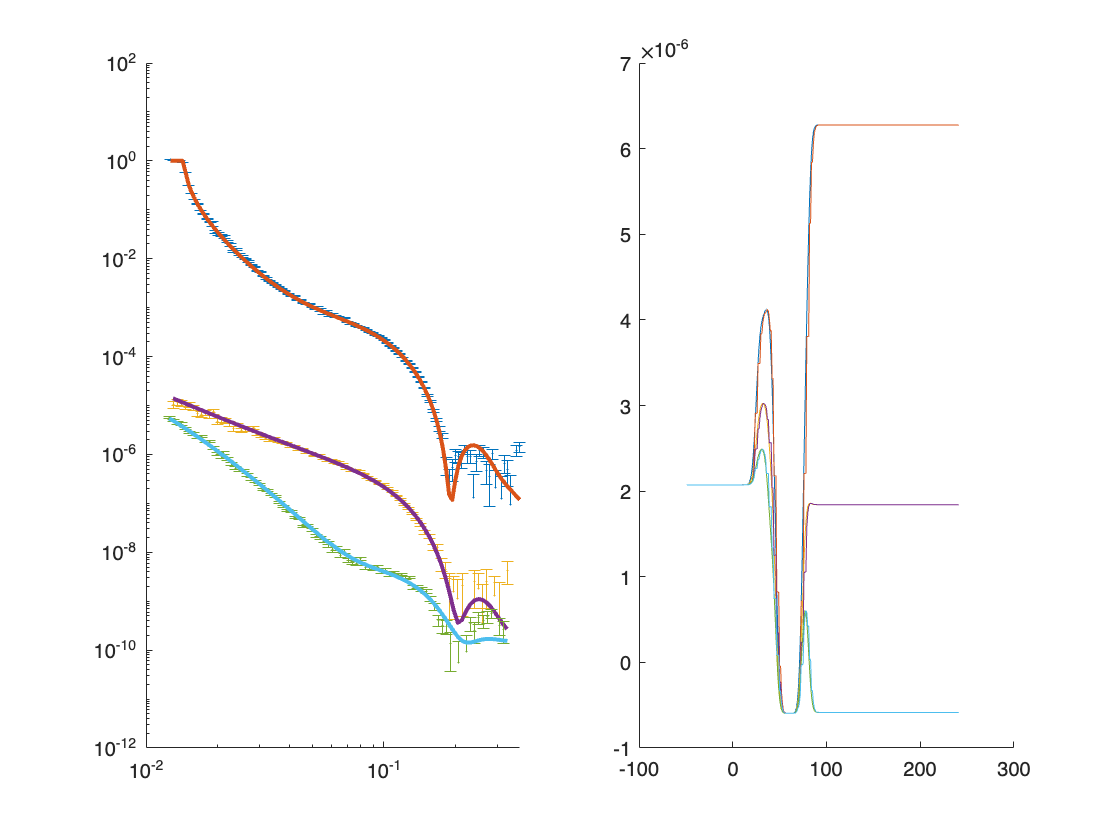

plotRefSLD(problem,results);

This is not too bad..... now run Bayes...

controls.procedure = 'dream';

controls.adaptPCR = true;
[problem,results] = RAT(problem,controls);

Starting RAT ________________________________________________________________________________________________


Running DREAM

------------------ Summary of the main settings used ------------------


DREAMPar = struct with fields:
             d: 14
             N: 10
             T: 5000
      parallel: 0
           CPU: 1
        lambda: 0.5000
    pUnitGamma: 0.2000
           nCR: 3
         delta: 3
         steps: 100
          zeta: 1.0000e-12
       outlier: 'iqr'
      adaptPCR: 1
      thinning: 1
       epsilon: 0.0250
           ABC: 0
            IO: 0
        modout: 0
       restart: 0
          save: 0
             R: [10×10 double]


-----------------------------------------------------------------------

 DREAM:    0.0% [........................................]


 DREAM:  100.0% [****************************************]
Elapsed time is 126.236177 seconds.

Finished RAT ______________________________________________________________________________________________ 



..and plot this out....

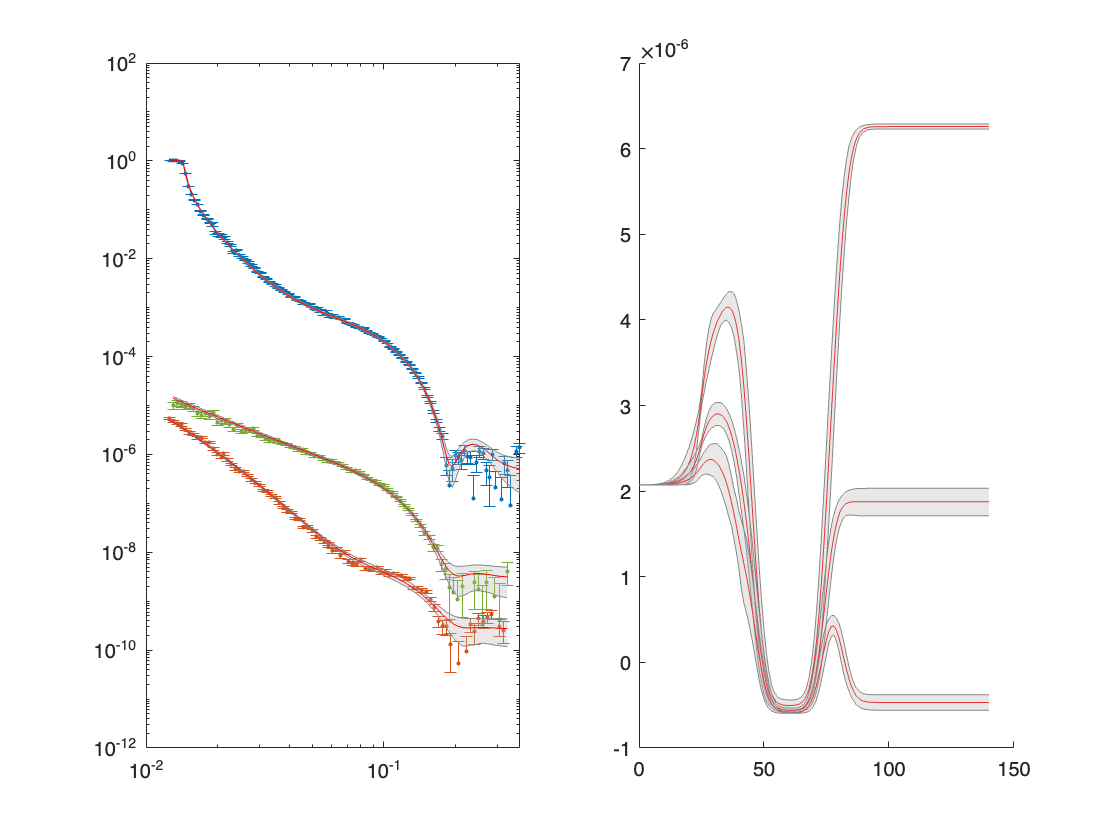

    figure(30); clf;
    bayesShadedPlot(problem, results,'fit','average','KeepAxes',true,'interval',65,'q4',false)

    
    h3 = figure(40); clf

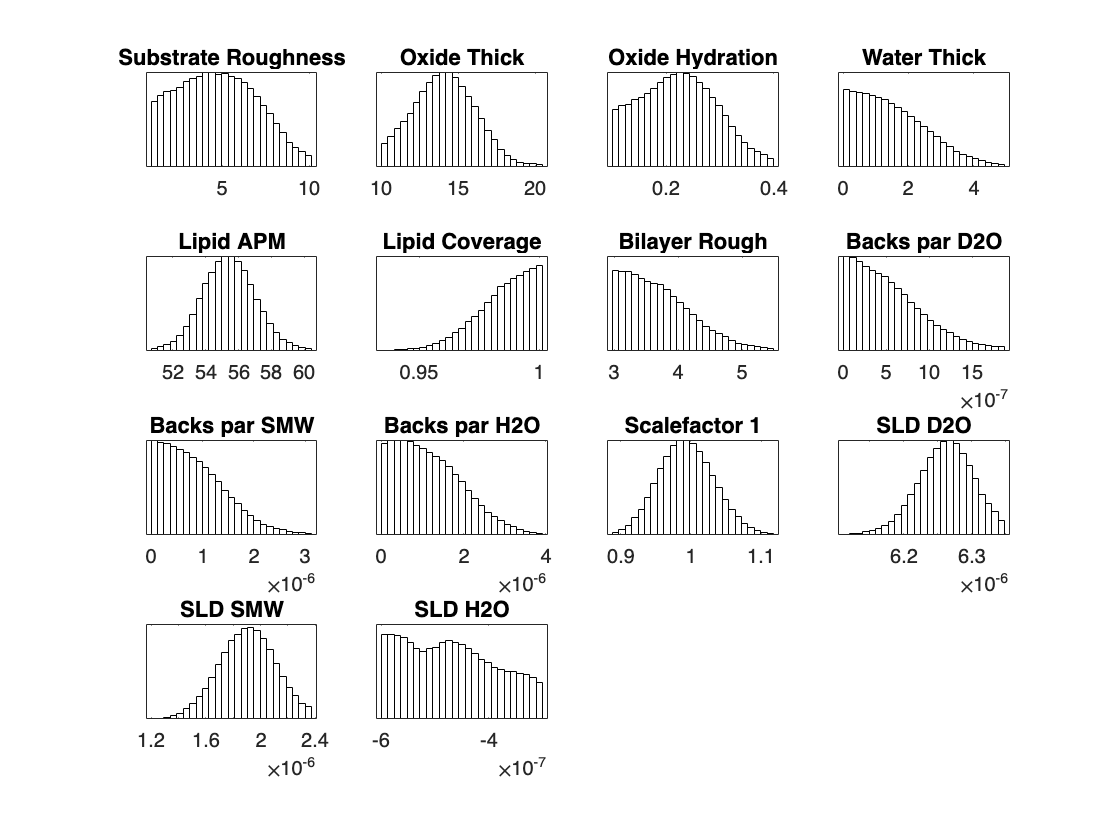

ans =   Axes (SLD H2O) with properties:

             XLim: [-6.0960e-07 -2.9040e-07]
             YLim: [0 4.4721e+06]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3361 0.1100 0.1566 0.1577]
            Units: 'normalized'

  Show all properties


    plotHists(results,h3,'smooth',true)

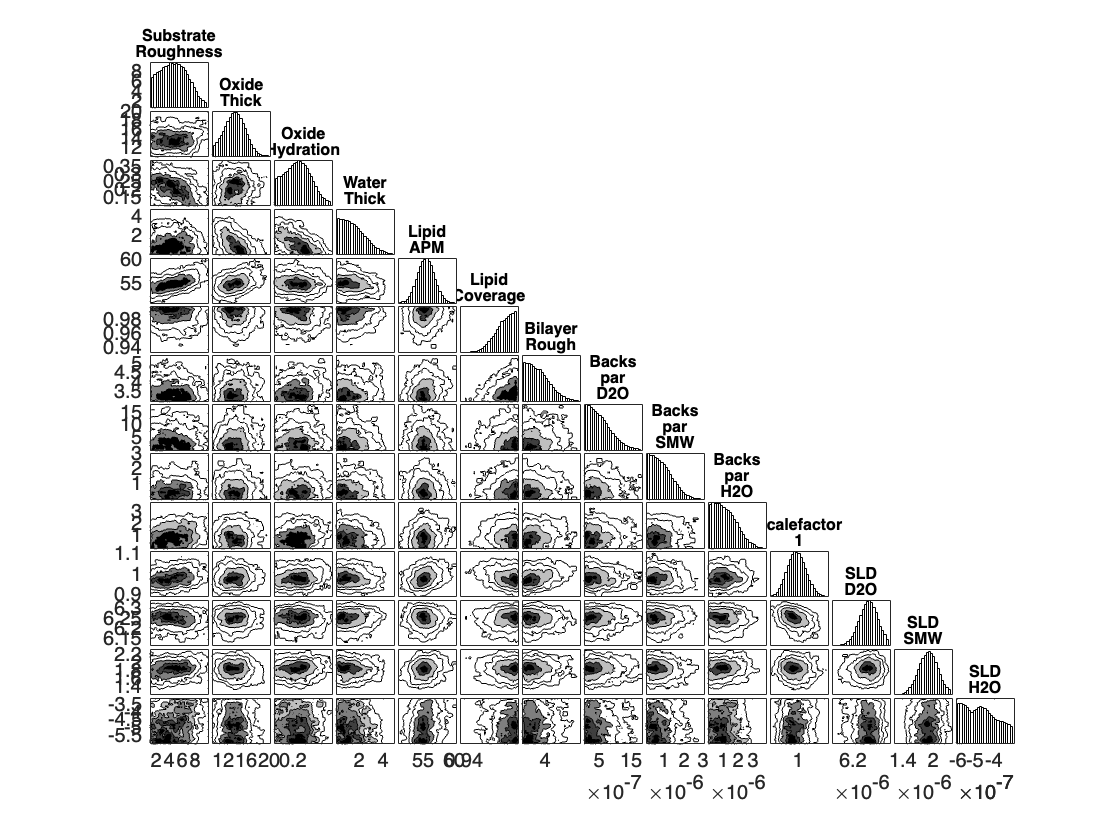

    
    h4 = figure(50); clf
    cornerPlot(results,h4,'smooth',false)

## A Slightly Deeper Analysys - Plotting The Bayes Result as Volume Fractions

The model we're using here is built using Volume Fractions. It's convenient to be able to use these as outputs, so that the result of our Bayesian analysis in terms of the VF's of the various components can be visualised. To do this, we make our global output flag true....

outputVF = true;

Now we have an output for our VF's.

We want to see how these are distributed in our Bayesian analysis. All the information comes from our chain....

    chain = results.chain;

Now, calculate the Volume Fractions for each sample of our Markov Chain, and store our VF outputs individual arrays....

    % Find the size of the chain
    nSamples = size(chain,1);

    % We don't need to calculate all of it, just take a random 1000 points
    % from the chain. Make a set of indicies...
    samples = randsample(nSamples,1000);

    % Make some empty arrays to store our data....
    vfSi = []; vfOxide = []; vfHeadL = []; vfTails = []; vfHeadR = []; vfWat = [];

    % Loop over all the samples...
    for n = 1:length(samples)
        % Take the n'th value from of set of indicies...
        i = samples(n);

        % Get these parameter values....
        thisParams = chain(i,:);

        % Run our model.....
        [~,~,thisRes] = customXYDSPC(thisParams,2.07e-6,6.35e-6,1);

        % Store them...
        thisVfs = thisRes(:,2:end); % Column 1 is the z value...

        % Add them to the arrays for storage...
        vfSi = [vfSi ; thisVfs(:,1)'];  % Note the transpose.....
        vfOxide  = [vfOxide ; thisVfs(:,2)'];
        vfHeadL  = [vfHeadL ; thisVfs(:,3)'];
        vfTails  = [vfTails ; thisVfs(:,4)'];
        vfHeadR  = [vfHeadR ; thisVfs(:,5)'];
        vfWat  = [vfWat ; thisVfs(:,6)'];
    end

For each collection of volume fractions, we need the mean and the 65% Percentile.....

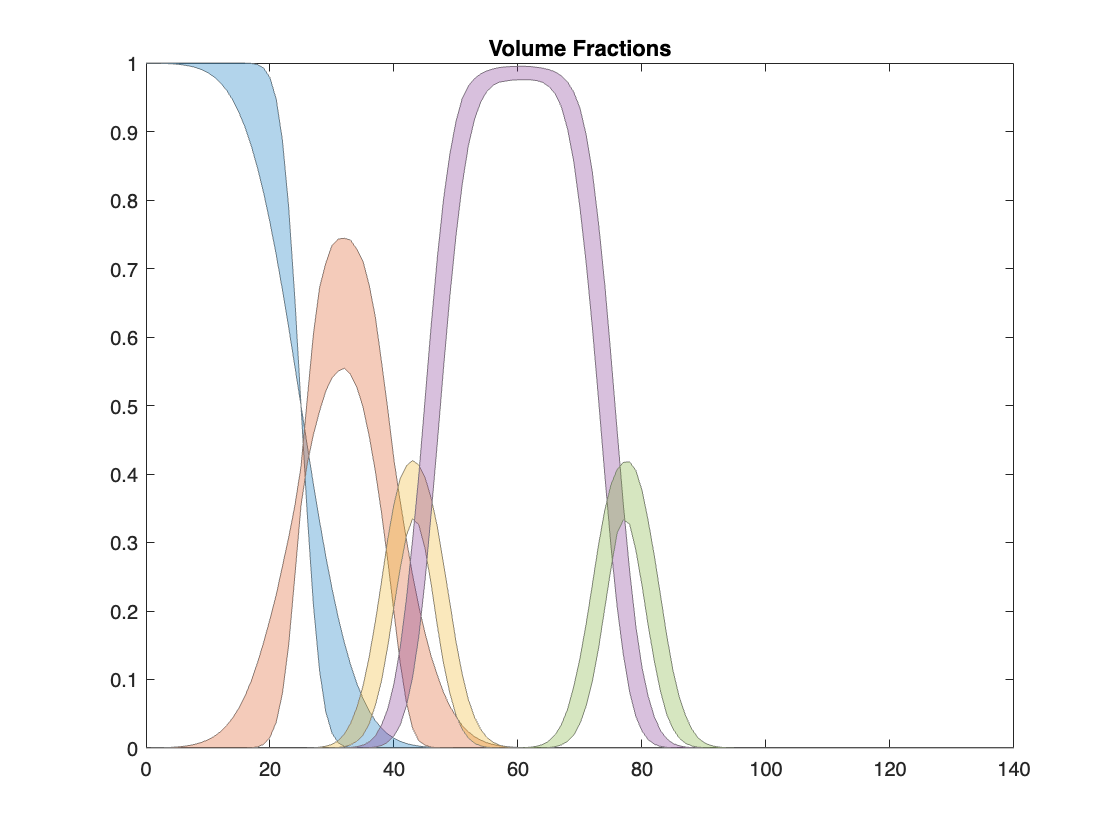

z = thisRes(:,1); nPoints = length(z);

% Make some empty arrays....
ciSi = []; ciOxide = []; ciHeadL = []; ciTails = []; ciHeadR = [];
avSi = []; avOxide = []; avHeadL = []; avTails = []; avHeadR = [];

% Make an inline function for calculating confidence intervals...
CIFn = @(x,p)prctile(x,abs([0,100]-(100-p)/2)); % Percentile function

% Work out average and confidence intervals...
avSi = mean(vfSi); ciSi = CIFn(vfSi,65);
avOxide = mean(vfOxide); ciOxide = CIFn(vfOxide,65);
avHeadL = mean(vfHeadL); ciHeadL = CIFn(vfHeadL,65);
avTails = mean(vfTails); ciTails = CIFn(vfTails,65);
avHeadR = mean(vfHeadR); ciHeadR = CIFn(vfHeadR,65);

% Make a plot.....
figure; hold on; box on

% In RAT, there is a useful function called 'shade' that we can use
% here.....
cols = get(gca,'ColorOrder');
shade(z,ciSi(1,:),z,ciSi(2,:),'FillColor',cols(1,:),'FillType',[1 2;2 1],'FillAlpha',0.3); 
shade(z,ciOxide(1,:),z,ciOxide(2,:),'FillColor',cols(2,:),'FillType',[1 2;2 1],'FillAlpha',0.3); 
shade(z,ciHeadL(1,:),z,ciHeadL(2,:),'FillColor',cols(3,:),'FillType',[1 2;2 1],'FillAlpha',0.3);
shade(z,ciTails(1,:),z,ciTails(2,:),'FillColor',cols(4,:),'FillType',[1 2;2 1],'FillAlpha',0.3);
shade(z,ciHeadR(1,:),z,ciHeadR(2,:),'FillColor',cols(5,:),'FillType',[1 2;2 1],'FillAlpha',0.3);
title('Volume Fractions');

.. and we are done.